### **Lab 1**

Phys 434

Daniel Rodriguez

October 11, 2020

**Problem 1- Standard Distribution**

**A) Standard-Normal Distribution**

Starting with the Equation for a Gaussian Distribution

$P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$  (**Eq. 1)**

Where,

$\mu$ = Mean (Center of the Gaussian Distribution), and

$\sigma \;$= Standard Deviation ( Spread of the Distribution).

In a Standard Distribution,

$z=\frac{\left(x-\mu \right)}{\sigma }$,      $\;\;\;\;\;\;\;\textrm{dz}=\frac{\textrm{dx}}{\sigma }$,

$\mu =0$, and                $\sigma =1$.

Yielding,

$P\left(x\right)\textrm{dx}=\frac{1}{\sqrt{2\pi }}e^{-\frac{z^2 }{2}} \textrm{dz}$   (**Eq. 2)**

for the Probability density equation.

mu=0;
sigma=1

sigma = 1


x=linspace(-15,15,201);
z=(x-mu)/sigma

z =   -15.0000  -14.8500  -14.7000  -14.5500  -14.4000  -14.2500  -14.1000  -13.9500  -13.8000  -13.6500  -13.5000  -13.3500  -13.2000  -13.0500  -12.9000  -12.7500  -12.6000  -12.4500  -12.3000  -12.1500  -12.0000  -11.8500  -11.7000  -11.5500  -11.4000  -11.2500  -11.1000  -10.9500  -10.8000  -10.6500  -10.5000  -10.3500  -10.2000  -10.0500   -9.9000   -9.7500   -9.6000   -9.4500   -9.3000   -9.1500   -9.0000   -8.8500   -8.7000   -8.5500   -8.4000   -8.2500   -8.1000   -7.9500   -7.8000   -7.6500


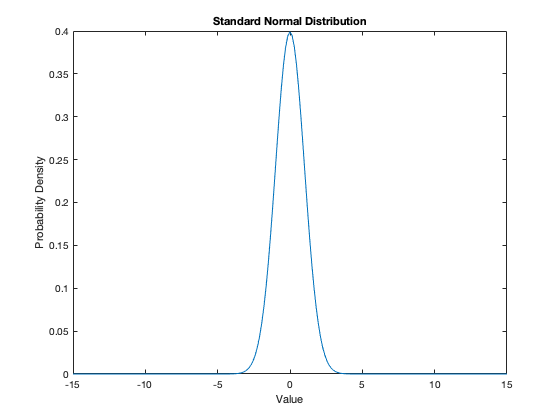


P_density=(1/(sigma*sqrt(2*pi))*exp(-(z).^2/(2)));
figure(35)
plot(x,P_density)
title('Standard Normal Distribution')
ylabel('Probability Density')
xlabel('Value')

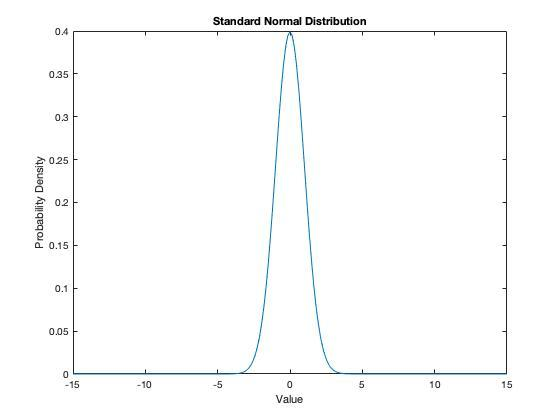

**B) Integrating Normal Distribution**

To find the probability a particular measurement will be the value x or lower we use the "normcdf" function of matlab. This function works by integrating the probability density for the Normal Distribution from a boundary x-value to infinity. This sum is then subtracted from 1 to get the probability desired. 

$\textrm{normcdf}\left(x\right)=\frac{1}{2}\textrm{erfc}\left(-\frac{x}{\sqrt{2}}\right)$       **(Eq. 3)**

where $\textrm{erfc}\left(x\right)=1-\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi }}\int_x^{\infty } e^{-z^2 } \textrm{dz}$.  **(Eq. 4)**

 Below, P outputs a certain probability that corresponds to a Standard-Normal Distribution, given a certain number of Standard Deviations (SD). Here we are integrating the probabilty density equation on on interval equal to the width of 1, 2, and 3 SDs. For example a 3 SD area corresponds to a 99.87% chance that a random measurement will fall below three standard deviations of the mean on a normally distributed dataset.

SD=[1; 2; 3];
mu=0;
sigma=1;
P=normcdf(SD,mu,sigma)

P =     0.8413
    0.9772
    0.9987


T= table(SD,P)

T = 3×2 table
    SD       P   
    __    _______

    1     0.84134
    2     0.97725
    3     0.99865


Here **mu **represents the mean and **sigma** represents the spread of the standard-normal distribution. SD represents the interval being integrated over, measured in standard deviations.

The code above generates this table of probabilities for 1, 2, and 3 standard deviations. 

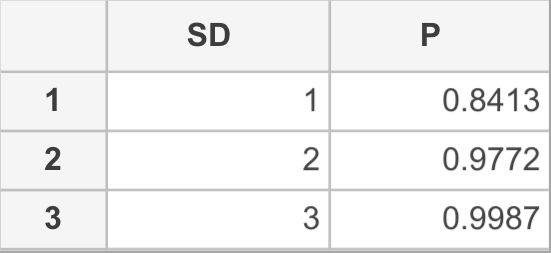

These can be compared to the table of Z-scores on Wiki, [https://en.wikipedia.org/wiki/Standard_normal_table.](https://en.wikipedia.org/wiki/Standard_normal_table.)

**C) The Inverse**

To find the Standard Deviation from the probability a value will land in a certain interval, given a Standard-Normal Distribution, we use the "norminv" MATLAB function. To further prove the correctness of both the forward and inverse of z-score/probability calculation I will use the probabilities gathered from the previous problem to generate the original Standard Deviations used: 1,2, and 3.

SD=norminv(P,mu,sigma)
T= table(SD,P)

**D) The Minus Sign**

One can see when a probability that is less than half of the distribution is chosen to calculate the inverse, a negative number for SD appears.

**Ex) **

SD=norminv(.46017,mu,sigma)


$$\;\;\;\textrm{SD}=-0\ldotp 01$$


This occurs because of how the area probability density function is calculated. One can think of it as always starting from the left tail and uniformly coloring in the area under the probability density curve with the probability calculated as the available ink. Looking at the normal distribution curve we see that it is centered on 0 so if you only have probability of less than 0.5 you're going to run out of ink before you get to the middle of the distribution. So your SD will be negative, or to the left of the mean.

**Problem 2- Lognormal**

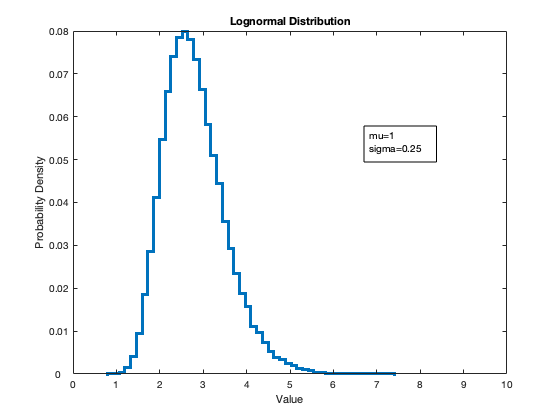

figure(2)
d = random('Lognormal', 1., .25, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([0,10])
ytix = get(gca, 'YTick'); 
set(gca, 'YTick',ytix, 'YTickLabel',ytix/100000);
title('Lognormal Distribution')
xlabel('Value')
ylabel('Probability Density')
str = {'mu=1', 'sigma=0.25'};
annotation('textbox', [0.65, 0.6, 0.1, 0.1], 'String', str, 'FitBoxToText','on')

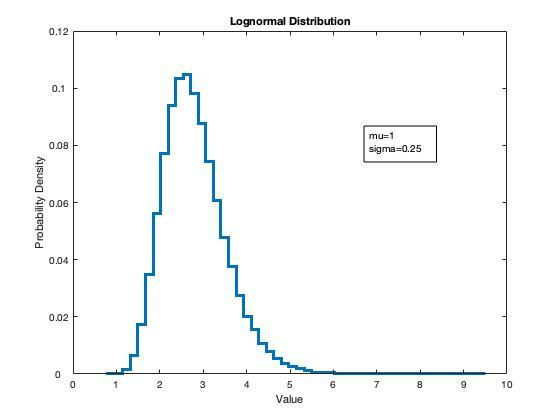

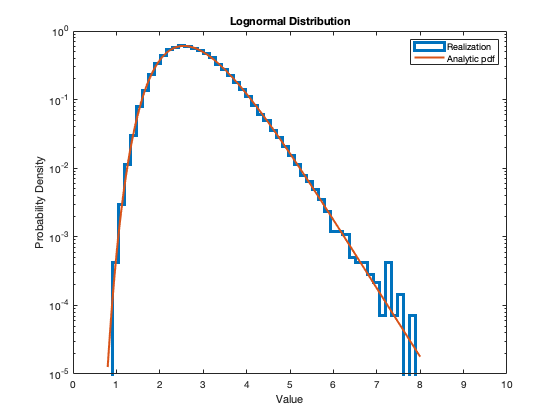

figure(13)
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on;
x = linspace(.8,8,1000);
pd = makedist("Lognormal","mu",1.,"sigma",.25);
Pdensity_Func=pdf(pd,x);
plot(x,Pdensity_Func,"LineWidth",2);
set(gca,'YScale','log')
xlim([0,10])
title('Lognormal Distribution')
xlabel('Value')
ylabel('Probability Density')
legend('Realization','Analytic pdf')

hold off;

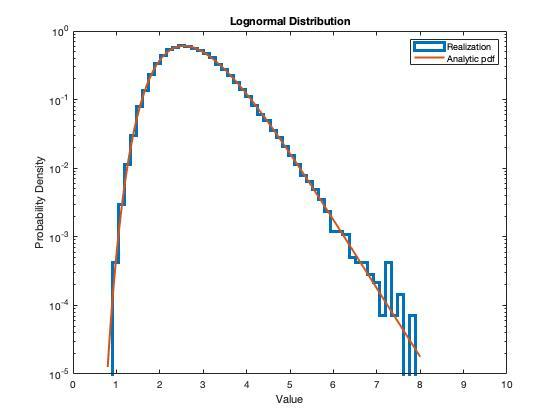

**3- Hypothetical Statistical Analysis**

**A) Hypothetical Value**

5 is the hypothetical experimental value that will be analyzed.

**B) Question**

Apparently, lengths of chess games tend to follow a lognormal distribution (http://chess.stackexchange.com/questions/2506/what-is-the-average-length-of-a-game-of-chess/4899#4899). 

Lets say we have a distribution of chess games played with a mean game time of 1 hour and a standard deviation of chess game length at 0.25. Is a 5 hour chess game an outlier in a lognormal distribution. An outlier will be defined as equal to or more than 3 standard deviations away from the mean.

**C) Mathematical Integral**

Probability density for a lognormal distribution is,

$f\left(x\right)=\frac{1}{\sqrt{2\pi }\sigma x}e^{-\frac{1}{2}\left(\frac{\left(\mathrm{ln}\left(x\right)-\mu \right)}{\sigma }\right)ˆ2}$.

Inserting our mu, and sigma of 1 and 0.25 we get,

$f\left(x\right)=\frac{4}{\sqrt{2\pi x}}{e^{-8\left(\mathrm{ln}\left(x\right)-1\right)} }^2$.

Cumulative probabilty from 0 to 5,


$$P=\int_0^5 f\left(x\right)\mathrm{dx}$$


Then we compare this probabilty to the required number of standard deviations away from the mean on a normal distribution to cover the same probability. This will be done in part D.

**D and E)**

Prob_lognormal=cdf('lognormal', 5, 1, 0.25);
SD=norminv(Prob_lognormal)

SD = 2.4372


$$\mathrm{SD}=2\ldotp 4372$$


We cannot conclude that a 5-hour chess game is an outlier based on our definition of an outlier.

**4- More Hypothetical Measurement Values**

Measuring 200 different x values from 0 to 10,

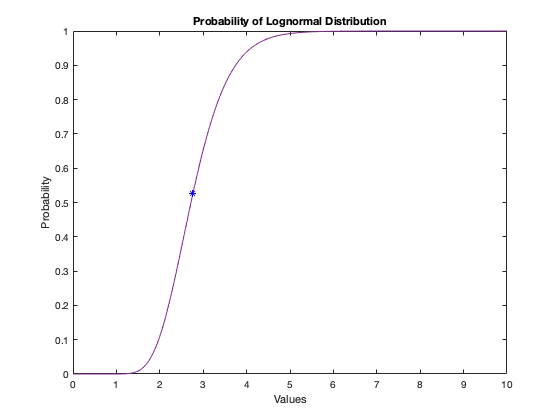

X_vals=linspace(0,10,200);

Prob_lognormal=cdf('lognormal', X_vals, 1, 0.25);
SD=norminv(Prob_lognormal);
figure(76)
plot(X_vals, Prob_lognormal)
xlabel('Values')
ylabel('Probability')
title('Probability of Lognormal Distribution')
hold on;
plot(X_vals(56),Prob_lognormal(56), '*b')

hold off;

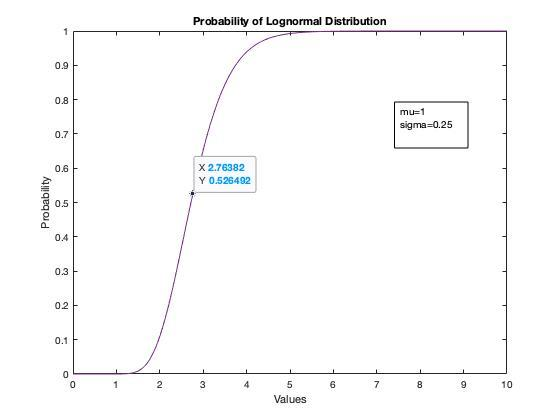

Here we see that the probability function's total area is halway integrated at approximately 2.75 for x. This differs from a normal distribution where this occurs right at the mean of 0, making a positive or negative value equally likely. The Lognormal distribution cannot have a negative value, because of the log operation. Causing the probability of the distribution to skew to the right of the mean, 1. However comparing the graph above with the graph of x-values vs SD we see something similar to the normal distribution.

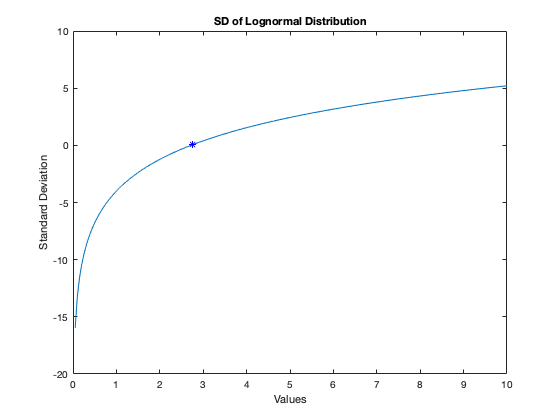


figure(89)
plot(X_vals, SD)
xlabel('Values')
ylabel('Standard Deviation')
title('SD of Lognormal Distribution')
hold on;
plot(X_vals(56),SD(56), '*b')

hold off;
T2=table(X_vals, Prob_lognormal,SD);

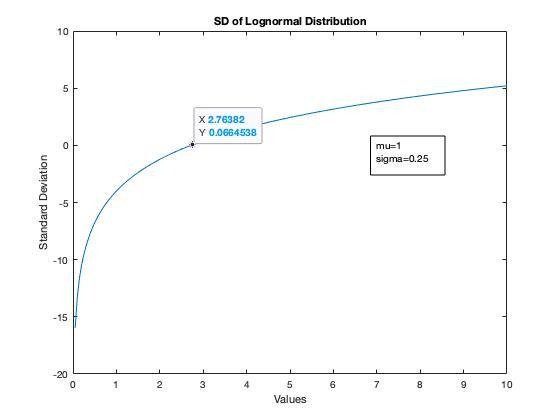

The x-value at which half of the probability density funciton area has been integrated is the x-value at which the standard deviation goes from negative to positive. This is due to the fact that the only difference in the way we "treat" the normal distribution vs. the lognormal distribution is the function we integrate.

**Non-Continuous Distributions**

**1- Poisson's Distribution.**

**A) Information on Poisson's Distribution.**

- Made up of discrete whole number integers only that aren't affected by the occurence of another measurement. For example, number of different people who call you on a regular day.

- Only parameters used are the mean, commonly denoted as $\lambda$, and the measurment values x.

**B)**

A common Poisson distribution looks like this,


lamda=3

lamda = 3

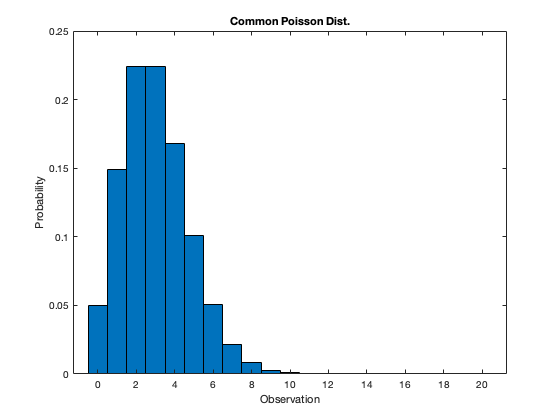

x = 0:20;
p = poisspdf(x,lamda);
figure(98)
bar(x,p,1)
xlabel('Observation')
ylabel('Probability')
title('Common Poisson Dist.')

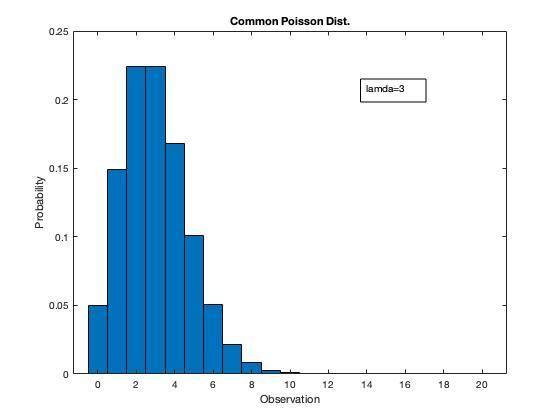

Here you can see that the entire distribution seems to be lop-sided to the left. The non-symmetrical nature about the mean comes from the fact that having a high count like 10, in this case, is unlikely but not impossible. Whereas having a negative count is impossible. Should the mean be large enough the distribution will look more symmetrical, and the Poisson distribution may be approximated by the normal distribution where,


$$\mu =\lambda ,\mathrm{and}$$


$\sigma =\sqrt{\lambda }$.

%Poisson's distribution with a large mean.
lamda=60

lamda = 60

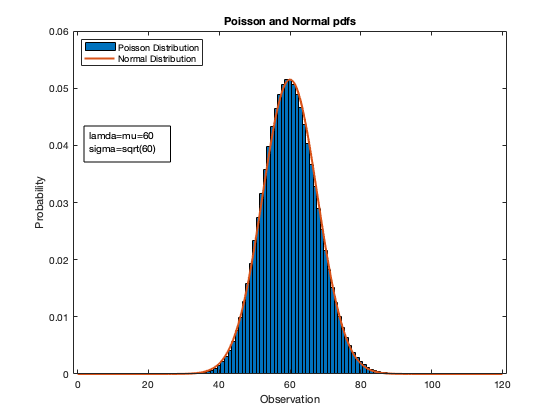

x1 = 0:120;
p1 = poisspdf(x1,lamda);

%Normal distribution with sigma and mu dependent on lambda.
mu=lamda;
sigma=sqrt(lamda);
x2=0:0.12:120;
p2=normpdf(x2,mu,sigma);

figure(45)
bar(x1,p1,1)
hold on
plot(x2,p2,'LineWidth',2)
xlabel('Observation')
ylabel('Probability')
title('Poisson and Normal pdfs')
legend('Poisson Distribution','Normal Distribution','location','northwest')
str = {'lamda=mu=60',  'sigma=sqrt(60)'};
annotation('textbox', [0.15, 0.6, 0.1, 0.1], 'String', str, 'FitBoxToText','on')
hold off

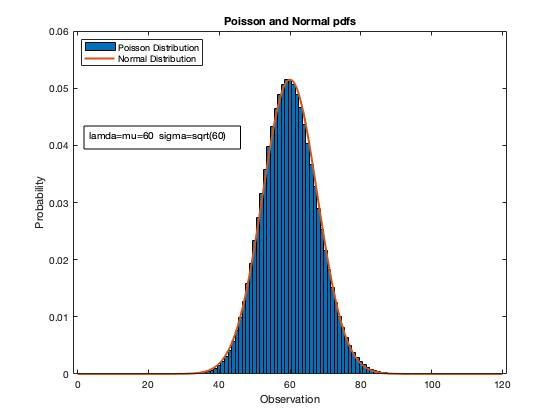

The Poisson distribution without the normal distribution approximation is best used when you expect to have a low positive count, such as number of nuclear decay events over 5 seconds, for some materials. Or number of lightning strikes in a day, in a small area.

**C) Hypothetical Question.**

What is the probability of aat least one Megathrust Earthquake occuring in the Cascadia Subduction Zone in the next 100 years?

Considering there have been 13 Megathrust Earthquakes(ME) in the last 6000 years (https://www.earthquakescanada.nrcan.gc.ca/zones/cascadia/qa-en.php#:~:text=The%20recurrence%20time%20varies%20from,they%20have%20not%20happened%20regularly.),  this dataset seems like a good canidate for Poisson's Distribution. You could make an arguement that the occurence of an earthquake affects the likelihood of another one happening but for the sake of arguement I am saying that it won't.

Statistically speaking a ME occurs every,

 
$$\frac{6000}{13}\approx 462\;\frac{\mathrm{years}}{\mathrm{ME}}\ldotp$$


That corresponds to an average, over a 100 year interval of,

$\frac{100}{462}\approx 0\ldotp 216\;\frac{\mathrm{ME}}{100\;\mathrm{years}}$.

Therfore,

$\lambda =0\ldotp 216$.

We are interested in at least 1 occurence in the next 100 years so our x-value will be 1.

x=1;
lamda=0.216;
Prob_ME=pdf('Poisson', x, lamda)

Prob_ME = 0.1740


$$P=0\ldotp 1740$$


Not too likely a ME will occur in the next 100 years, but not impossible. Again, this is assuming the time of occurence of previous quakes does not affect the time of occurence for the next one.

**D) **

One very important thing to assess is whether or not your time interval makes sense. If events cannot happen at the same time and you make your interval very small you'll only get counts of 0 and 1 and therefore probabilities of 0 or 1. If you make the interval unnescessarily large, your data collection will be slowed, wasting time.

**E)**

For Poisson's distribution you can only get positive or no counts. There is no room for negative counts. So you could concievably have any positive number as the mean of a distribution. Since the mean is constantly re-measured over a multiple time intervals that are continuous when put together it is constantly in the process of changing.